% chenzhe, 2019-09-03
% It is likely useful to manually label twin-gb intersection.  We need some ground truth data anyway.


clear;
addChenFunction;

% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

% [data] strain data. Convert into v7.3 for partial loading
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result, for reference.
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));


## Find triple points

[boundary,~, ~, tripleTF, ~, indTriple, tripleIDs] = find_one_boundary_from_ID_matrix(ID);
xTriple = X(indTriple);
yTriple = Y(indTriple);

## Select an iS to start

plotTF = 0;
pauseTF = 0;
umPerX = 360/4096;
umPerDp = 360/4096*5;
calculateQuants = 0;    % after assigning twin-gb to different categories, calculate quants, which is slow.

for iE = 2:5
    variableNames = {'iE','ID','gDia','ID_neighbor','gDia_neighbor','TS','TSF',...
        'incoming','iiE_each_twin','iiE_each_twin_at_this_boundary','intersection_to_triple','iiE_twins_at_this_boundary_Nb',...
        'mPrime','rank_mPrime','ssn_neighbor','SF_neighbor',...
        'resB','rank_resB','ssn_neighbor_r','SF_neighbor_r',...
        'initiating'};
    T = cell2table(cell(0,length(variableNames)));
    T.Properties.VariableNames = variableNames;
    T_template = T;
    
    % summary of [bNum, gNum] pairs list, for different categories of activities
    % (1) not involved, (2) slip-induced-twin, slip side, (3) slip-induced-twin, twin side,
    % (4) co-found, (5) twin-induced-twin, old twin side, (6) twin-induced-twin, new twin side,
    % (7) slip-induced-growth, slip side, (8) slip-induced-growth, twin side, (9) co-growth
    bg_not_involved = [];
    bg_slip_twin_a = [];
    bg_slip_twin_b =[];
    bg_co_found = [];
    bg_twin_twin_a = [];
    bg_twin_twin_b = [];
    bg_slip_growth_a = [];
    bg_slip_growth_b = [];
    bg_co_growth = [];
    
    % The purpose of this code is mainly compare intiation vs existing twin-slip pair, study the [effect of mPrime]
    iS = 1;
    warning('off','MATLAB:table:RowsAddedExistingVars');
    continueTF = true;
    dToTriple_th = 5;       % eliminate intersection whose distance to triple point is smaller than this value
    dToTriple_th_to_label = 3;  % label if distance of intersection to triple point is smaller than this value
    
    hW = waitbar(0, ['iE=',num2str(iE),' analyze each grain']);
    hN = length(struCell{iE});
    while (continueTF)&&(iS<=length(struCell{iE}))
        waitbar(iS/hN, hW);
        
        % If grain of interest is twinned
        if sum(struCell{iE}(iS).cTrueTwin(:))>0  % ismember(struCell{iE}(iS).gID, twinned_grain_list)
            %%
            close all;
            ID_current = struCell{iE}(iS).gID;
            ind = find(gID==ID_current);
            
            euler = [gPhi1(ind),gPhi(ind),gPhi2(ind)];
            if (1==eulerAligned)
                % g = euler_to_transformation(euler,[0,0,0],[0,0,0]);
                [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler, [0,0,0], [0,0,0], stressTensor, sampleMaterial, 'twin');
            else
                % g = euler_to_transformation(euler,[-90,180,0],[0,0,0]); % setting-2
                [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler, [-90,180,0], [0,0,0], stressTensor, sampleMaterial, 'twin'); % setting-2
            end
            [ssa, c_a, nss, ntwin, ssGroup] = define_SS(sampleMaterial,'twin');
            traceDir = abs_schmid_factor(nss+1:nss+ntwin,3);
            
            nNeighbors = gNNeighbors(ind);
            ID_neighbors = gNeighbors(ind, 1:nNeighbors);
            
            ind_local = ismember(ID, [ID_current, ID_neighbors]); %ismember(ID, [ID_current,ID_neighbor]);
            
            % Make it one data point wider on each side
            indC_min = max(1, find(sum(ind_local, 1), 1, 'first')-1);
            indC_max = min(size(ID,2), find(sum(ind_local, 1), 1, 'last')+1);
            indR_min = max(1, find(sum(ind_local, 2), 1, 'first')-1);
            indR_max = min(size(ID,1), find(sum(ind_local, 2), 1, 'last')+1);
            
            ID_local = ID(indR_min:indR_max, indC_min:indC_max);
            X_local = X(indR_min:indR_max, indC_min:indC_max);
            Y_local = Y(indR_min:indR_max, indC_min:indC_max);
            uniqueBoundary_local = uniqueBoundary(indR_min:indR_max, indC_min:indC_max);
            boundaryTF_local = boundaryTF(indR_min:indR_max, indC_min:indC_max);
            trueTwinMapLocal = trueTwinMapCell{iE}(indR_min:indR_max, indC_min:indC_max);
            e_local = strainFile{iE}.exx(indR_min:indR_max, indC_min:indC_max);
            
            if plotTF==1
                %         [handleFig0,a1,~] = myplot(X_local, Y_local, e_local, boundaryTF_local);
                %         disableDefaultInteractivity(a1);
                %         [handleFig,aa,~] = myplot(X_local, Y_local, trueTwinMapLocal, boundaryTF_local);
                %         caxis([18 24]);
                [handleFig,aa,~] = myplot(X_local, Y_local, e_local, boundaryTF_local);  % boundaryTF_local_2 = find_boundary_from_ID_matrix(trueTwinMapLocal>0)|(boundaryTF_local);
                label_map_with_ID(X_local, Y_local, ID_local, handleFig, ID_current);
                disableDefaultInteractivity(aa);
                hold on;
            end
            
            % find out grain size
            gDia = sqrt(4*(struCell{iE}(iS).gVol* (umPerDp)^2)/pi);
            % Find active system, if any, using cTrueTwin
            activeTS = sum(struCell{iE}(iS).cTrueTwin,1)>0;
            tSF = struCell{iE}(iS).tSF;
            
            mPrime_table = [];
            resB_table = [];
            T_local = T_template;
            
            % [[[[For each neighbor]  get stats about neighbor and plot, such as m'
            for iNb = 1:nNeighbors
                ID_neighbor = ID_neighbors(iNb);
                
                % (1.1) Calculate this_uniqueGB number.
                if ID_current > ID_neighbor
                    gb = ID_current * 10000 + ID_neighbor;
                else
                    gb = ID_neighbor * 10000 + ID_current;
                end
                
                ind_of_indTriple = sum(ismember(tripleIDs,ID_current) + ismember(tripleIDs,ID_neighbor),2)==2;
                xTriple_local = X(indTriple(ind_of_indTriple));
                yTriple_local = Y(indTriple(ind_of_indTriple));
                
                % Find [iE, iTwin, dToTriple] on the grain_of_interest side, then on the neighboring side
                [iE_iTwin_dT_list, valid_grain_a] = find_activity_at_boundary_from_struCell(struCell, iE, ID_current, gb, [xTriple_local, yTriple_local]);
                iE_iTwin_dT_list(:,3) = iE_iTwin_dT_list(:,3) * umPerX;   % --> because unit is 'x/y coordinate' rather than 'data point/index', do not need to use the factor of 5.
                iiE_each_twin = find_initial_iE_of_twin_in_grain(struCell, ID_current);
                % repeat for the neighbor
                [iE_iTwin_dT_list_Nb, valid_grain_b] = find_activity_at_boundary_from_struCell(struCell, iE, ID_neighbor, gb, [xTriple_local, yTriple_local]);
                iE_iTwin_dT_list_Nb(:,3) = iE_iTwin_dT_list_Nb(:,3) * umPerX;
                iiE_of_each_twin_Nb = find_initial_iE_of_twin_in_grain(struCell, ID_neighbor);
                
                if (valid_grain_a)&&(valid_grain_b)
                    % (1.2) Find which of the active twin systems in the grain are 'incoming' to this grain boundary
                    % In addition, we need to find out if this twin first appear at this grain boundary.
                    incoming_TS = zeros(1,6);           % IF the twin system is active on the grain of interest side of the boundary
                    iiE_each_iTwin_at_this_boundary = inf * ones(1,6);    % the first iE that this twin shown at this gb
                    an_initiating_boundary_of_twin = zeros(1,6);    % IF the twin was at this boundary at the iE that it just activated, 'an' initiating rather than 'the' initiating
                    intersection_to_triple = nan*zeros(6,1);    % Distance of intersection to triple point
                    twin_at_triple = zeros(6,1);        % In fact no need to label.  Just compare intersection_to_triple to a distance should be enough.  % Does this twin only intersect gb close to triple point
                    
                    for iTwin = 1:6
                        ind = (iE_iTwin_dT_list(:,2)==iTwin)&(iE_iTwin_dT_list(:,3)>dToTriple_th); % This considers TriplePoint, eliminating intersections too close to triple points
                        if any(ind)
                            incoming_TS(iTwin) = 1;
                            iiE_each_iTwin_at_this_boundary(iTwin) = min(iE_iTwin_dT_list(ind,1));
                            if iiE_each_iTwin_at_this_boundary(iTwin) == iiE_each_twin(iTwin)
                                an_initiating_boundary_of_twin(iTwin) = 1;
                            end
                            
                            dmax = max(iE_iTwin_dT_list(ind,3),[],1);                  % the largest among distance_to_the_closest_triple_point
                            intersection_to_triple(iTwin) = dmax;
                            
                            % If this is still very small, say less than [3 micron] to triple point
                            if dmax < dToTriple_th_to_label
                                twin_at_triple(iTwin) = 1;
                                indr = find(dmax == iE_iTwin_dT_list(:,3));
                                text(iE_iTwin_dT_list(indr,4), iE_iTwin_dT_list(indr,5), 50, [num2str(dmax)], 'color','b','fontsize',36);
                            end
                        end
                    end
                    
                    if sum(incoming_TS)==0
                        have_incoming_twin_at_boundary = 0;
                    else
                        have_incoming_twin_at_boundary = 1;
                    end
                    
                    
                    % ---------------> What if neighbor intersect close to a triple point?  Need to add some considerations?      ---------------------------???????????
                    % (1.3) Similarly, find if this neighbor grain (ID_neighbor) is twinned.
                    % If twinned, and twin intersect this_uniqueGB, consider only these intersecting twins
                    % else, consider only basal in this_neighbor
                    iS_neighbor = find(arrayfun(@(x) x.gID == ID_neighbor, struCell{iE}));
                    if ~isempty(iS_neighbor)
                        gDia_neighbor = sqrt(4*(struCell{iE}(iS_neighbor).gVol* (360/4096*5)^2)/pi);
                        activeTS_Nb = sum(struCell{iE}(iS_neighbor).cTrueTwin,1)>0;
                        
                        % repeat for the neighbor.  The only difference is that, do not care if it is 'an' initiating boundary.  Just care if it is twinned
                        outgoing_TS = zeros(1,6);           % IF the twin system is active on the grain of interest side of the boundary
                        iiE_each_twin_at_this_boundary_Nb = inf * ones(1,6);    % the first iE that this twin shown at this gb
                        intersection_to_triple_Nb = nan*zeros(6,1);    % Distance of intersection to triple point
                        twin_at_triple_Nb = zeros(6,1);        % Does this twin only intersect gb close to triple point
                        
                        for iTwin = 1:6
                            ind = (iE_iTwin_dT_list_Nb(:,2)==iTwin)&(iE_iTwin_dT_list_Nb(:,3)>dToTriple_th);	% This considers TriplePoint, eliminating intersections too close to triple points
                            if any(ind)
                                outgoing_TS(iTwin) = 1;     % With d_to_triple considered
                                iiE_each_twin_at_this_boundary_Nb(iTwin) = min(iE_iTwin_dT_list_Nb(ind,1));
                                
                                dmax = max(iE_iTwin_dT_list_Nb(ind,3),[],1);                  % the largest among distance_to_the_closest_triple_point
                                intersection_to_triple_Nb(iTwin) = dmax;
                                if dmax < dToTriple_th_to_label
                                    twin_at_triple_Nb(iTwin) = 1;
                                    indr = find(dmax == iE_iTwin_dT_list_Nb(:,3));
                                    text(iE_iTwin_dT_list_Nb(indr,4), iE_iTwin_dT_list_Nb(indr,5), 50, [num2str(dmax)], 'color','b','fontsize',36);
                                end
                            end
                        end
                        
                        
                        if sum(outgoing_TS)==0
                            % Only basal in this_Nb
                            outgoing_basal = 1;
                            outgoing_ss_n = [1 2 3];
                        else
                            outgoing_basal = 0;
                            outgoing_ss_n = 19:24;
                            outgoing_ss_n = outgoing_ss_n(logical(outgoing_TS));
                        end
                        
                        % Calculate mPrime
                        ind_Nb = find(gID==ID_neighbor);
                        euler_Nb = [gPhi1(ind_Nb),gPhi(ind_Nb),gPhi2(ind_Nb)];
                        [schmidFactorG1, schmidFactorG2, mPrimeMatrix, resBurgersMatrix, mPrimeMatrixAbs, resBurgersMatrixAbs] = calculate_mPrime_and_resB(euler, euler_Nb, stressTensor, [1 0 0], sampleMaterial, 'twin');
                        
                        [max_basal_SF_Nb, ~] = max(schmidFactorG2(1:3));
                        [max_twin_SF_Nb, ~] = max(schmidFactorG2(19:24));
                        
                        % Based on whether considering basal or twin in this neighbor, do different things: ...
                        % (3) label basal/twin slip trace
                        ID_target = ID_neighbor;
                        if plotTF==1
                            local_fun_label_map_with_ID_and_trace(X_local,Y_local,ID_local,ID_target, outgoing_ss_n, gca);
                        end
                        % find SFs in the neighbor grain
                        SFs_Nb = schmidFactorG2(outgoing_ss_n);
                        
                        
                        % [[[[--> maybe it's better to find potential basal. e.g., all those with sf > 0.3, or normalized > 0.8
                        % [max_sf, ind_max_sf] = max(SFs_Nb);
                        potential_ss = (SFs_Nb>0.25) | (SFs_Nb./max(SFs_Nb)>0.8);   % logical vector, indicating wheter the out-going ss is considered as able to be activated (e.g., SF high enough)
                        
                        mPrimeMatrixAbs = round(mPrimeMatrixAbs,4);     % [important detail] round to reduce ranking error, otherwise small diff can cause rank difference, e.g., same value ranked no. 1,2,3,4
                        
                        mPrime_local = mPrimeMatrixAbs(19:24, outgoing_ss_n);
                        [mPrime_each_twin, ind_in_outgoing_n] = max(mPrime_local.*reshape(potential_ss,1,[]),[],2);
                        ssn_each_twin = outgoing_ss_n(ind_in_outgoing_n);   % ssn in neighbor, for each ts in the grain of interest
                        SF_each_twin = SFs_Nb(ind_in_outgoing_n);           % SF of that ss in neighbor, for each ts in the grain of interest
                        mPrime_table = [mPrime_table, mPrime_each_twin];
                        [sorted_mPrime_each_twin,~] = sort(mPrime_each_twin,'descend');
                        [~,rank_mPrime_each_twin] = ismember(mPrime_each_twin, sorted_mPrime_each_twin);
                        % find the mPrime to plot. ------> Note that for each boundary, only one mPrime and rank is selected.  But for each twin system, there is an mPrime.
                        if have_incoming_twin_at_boundary
                            [mPrime, ind_mPrime] = max(mPrime_each_twin.*incoming_TS(:));
                            mPrime_rank = rank_mPrime_each_twin(ind_mPrime);
                        else
                            [mPrime, ind_mPrime] = max(mPrime_each_twin.*activeTS(:));
                            mPrime_rank = rank_mPrime_each_twin(ind_mPrime);
                        end
                        
                        resBurgersMatrixAbs = round(resBurgersMatrixAbs,4);
                         
                        resB_local = resBurgersMatrixAbs(19:24, outgoing_ss_n);
                        resB_local(:,potential_ss==0) = inf; % [detail] artificially make it 'inf' to avoid being found.   
                        [resB_each_twin, ind_in_outgoing_n] = min(resB_local,[],2);
                        ssn_each_twin_r = outgoing_ss_n(ind_in_outgoing_n);
                        SF_each_twin_r = SFs_Nb(ind_in_outgoing_n);
                        resB_table = [resB_table, resB_each_twin];
                        [sorted_resB_each_twin,~] = sort(resB_each_twin,'ascend');
                        [~,rank_resB_each_twin] = ismember(resB_each_twin, sorted_resB_each_twin);
                        % find the resB to plot
                        if have_incoming_twin_at_boundary
                            [resB, ind_resB] = min(resB_each_twin./incoming_TS(:));
                            resB_rank = rank_resB_each_twin(ind_resB);
                        else
                            [resB, ind_resB] = min(resB_each_twin./activeTS(:));
                            resB_rank = rank_resB_each_twin(ind_resB);
                        end
                        
                        % [NOTE] --> Draw mPrime and color, but label ResB, to maximize information provided.
                        if plotTF==1
                            inds = find(uniqueBoundary_local==gb);
                            plot(X_local(inds),Y_local(inds),'.','markersize',18,'color',[1 1 0] * mPrime);
                            if outgoing_basal==1
                                text(mean(X_local(inds)), mean(Y_local(inds)), 50, [num2str(mPrime_rank + mPrime,4)], 'color','r','fontsize',16);
                            else
                                text(mean(X_local(inds)), mean(Y_local(inds)), 50, [num2str(mPrime_rank + mPrime,4)], 'color','b','fontsize',16);
                            end
                        end
                        
                        % Extend table for summary.  -- can assign in local table using name?
                        for iTwin=1:6
                            % T_local = [T_local;{iE, ID_current, gDia, ID_neighbor, gDia_neighbor, iTwin, tSF(iTwin), incoming_TS(iTwin), ...
                            %     mPrime_each_twin(iTwin), rank_mPrime_each_twin(iTwin), ssn_each_twin(iTwin), SF_each_twin(iTwin), ...
                            %     resB_each_twin(iTwin), rank_resB_each_twin(iTwin), ssn_each_twin_r(iTwin), SF_each_twin_r(iTwin), ...
                            %     intersection_to_triple(iTwin), twin_at_triple(iTwin), ts_first_appear_here(iTwin), false}];
                            ir = size(T_local,1) + 1;
                            T_local.iE(ir) = iE;
                            T_local.ID(ir) = ID_current;
                            T_local.gDia(ir) = gDia;
                            T_local.ID_neighbor(ir) = ID_neighbor;
                            T_local.gDia_neighbor(ir) = gDia_neighbor;
                            T_local.TS(ir) = iTwin;
                            T_local.TSF(ir) = tSF(iTwin);
                            
                            T_local.incoming(ir) = incoming_TS(iTwin);
                            T_local.iiE_each_twin(ir) = iiE_each_twin(iTwin);
                            T_local.iiE_each_twin_at_this_boundary(ir) = iiE_each_iTwin_at_this_boundary(iTwin);
                            T_local.intersection_to_triple(ir) = intersection_to_triple(iTwin);
                            T_local.iiE_twins_at_this_boundary_Nb(ir) = min(iiE_each_twin_at_this_boundary_Nb);
                            
                            T_local.mPrime(ir) = mPrime_each_twin(iTwin);
                            T_local.rank_mPrime(ir) = rank_mPrime_each_twin(iTwin);
                            T_local.ssn_neighbor(ir) = ssn_each_twin(iTwin);
                            T_local.SF_neighbor(ir) = SF_each_twin(iTwin);
                            
                            T_local.resB(ir) = resB_each_twin(iTwin);
                            T_local.rank_resB(ir) = rank_resB_each_twin(iTwin);
                            T_local.ssn_neighbor_r(ir) = ssn_each_twin_r(iTwin);
                            T_local.SF_neighbor_r(ir) = SF_each_twin_r(iTwin);
                            
                            T_local.initiating(ir) = false;
                        end
                        
                        % need to determine iE_g and iE_n
                        ir = iE_iTwin_dT_list(:,3) > dToTriple_th;
                        iE_g = min(iE_iTwin_dT_list(ir,1));
                        ir = iE_iTwin_dT_list_Nb(:,3) > dToTriple_th;
                        iE_n = min(iE_iTwin_dT_list_Nb(ir,1));
                        if isempty(iE_g)
                            iE_g = inf;
                        end
                        if isempty(iE_n)
                            iE_n = inf;
                        end
                        % above: need to artificially make it 'inf' in case it is empty
                        
                        if (iE_g>iE)||(isempty(iE_g))
                            if (iE_n>iE)||(isempty(iE_n))
                                % not involved
                                bg_not_involved = [bg_not_involved; gb, ID_current];
                            elseif (iE_n==iE)
                                % slip induced twin, slip side
                                bg_slip_twin_a = [bg_slip_twin_a; gb, ID_current];
                            elseif (iE_n<iE)
                                % slip induced twin growth, slip side
                                bg_slip_growth_a = [bg_slip_growth_a; gb, ID_current];
                            end
                        elseif (iE_g==iE)
                            % just twinned this grain
                            if (iE_n>iE)||(isempty(iE_n))
                                % slip induced twin, twin side
                                bg_slip_twin_b = [bg_slip_twin_b; gb, ID_current];
                            elseif (iE_n==iE)
                                % co-found twin
                                bg_co_found = [bg_co_found; gb, ID_current];
                            elseif (iE_n<iE)
                                % twin induced twin, new twin side
                                bg_twin_twin_b = [bg_twin_twin_b; gb, ID_current];
                            end
                        elseif (iE_g<iE)
                            % twinned this grain
                            if (iE_n>iE)||(isempty(iE_n))
                                % slip induced twin growth, twin side
                                bg_slip_growth_b = [bg_slip_growth_b; gb, ID_current];
                            elseif (iE_n==iE)
                                % twin induced twin, old twin side
                                bg_twin_twin_a = [bg_twin_twin_a; gb, ID_current];
                            elseif (iE_n<iE)
                                % co-growth
                                bg_co_growth = [bg_co_growth; gb, ID_current];
                            end
                        end
                    end
                    
                end
            end
            
            % 'incoming_TS' just means intersecting.  Each twin can intersect several gbs.
            % We want to find the one with the (highest m') to represent the initiating point.
            % But there are potential pairs of slip/twin we can choose from.  The basic one is to s
            for iTwin = 1:6
                rows = find((T_local.TS==iTwin)&(T_local.iiE_each_twin==T_local.iiE_each_twin_at_this_boundary));
                rows = find((T_local.TS==iTwin)&(T_local.iiE_each_twin==T_local.iiE_each_twin_at_this_boundary)&(T_local.gDia>80)&(T_local.gDia_neighbor>80));
                if ~isempty(rows)
                    [~,ind] = max(T_local.mPrime(rows,:));
                    T_local.initiating(rows(ind)) = 1;
                    % disp(['Twin ',num2str(iTwin),' first appear, initiatiated from neighbor ID:',num2str(T_local.ID_neighbor(rows(ind)))]);
                end
            end
            ind = (T_local.initiating==1);
            label_map_with_ID(X_local,Y_local,ID_local,gcf,T_local.ID_neighbor(ind),'m');
            T = [T;T_local];
            
            if plotTF==1
                % (3) Draw previously labeled lines
                for iTwin = 1:6
                    tGbNormals = struCell{iE}(iS).tGbNormal{iTwin};
                    for iGb = 1:length(tGbNormals)
                        if ~isempty(tGbNormals{iGb})
                            for iLine = 1:length(tGbNormals{iGb})
                                drawline(aa,'Position',tGbNormals{iGb}{iLine},'color','m','linewidth',1);
                            end
                        end
                    end
                end
                
                if pauseTF==1
                    needToAdd = questdlg('Continue, pause, or cancel','select answer','continue','pause','cancel','continue');
                    switch needToAdd
                        case 'pause'
                            continueTF = false;
                            hgexport(gcf,'-clipboard');
                        case 'continue'
                            continueTF = true;
                            hgexport(gcf,'-clipboard');
                        case 'cancel'
                            iS = iS - 1;    % when cancel, reduce by 1 first
                            continueTF = false;
                    end
                end
                saveas(gcf,['temp_results\iE_',num2str(iE),'_ID_',num2str(ID_current),'.tiff']);
            end
            
        else
            % If grain of interest is not twinned, this means (iE_g > iE)
            ID_current = struCell{iE}(iS).gID;
            ind = find(gID==ID_current);
            nNeighbors = gNNeighbors(ind);
            ID_neighbors = gNeighbors(ind, 1:nNeighbors);
            
            for iNb = 1:nNeighbors
                ID_neighbor = ID_neighbors(iNb);
                % (1.1) Calculate this_uniqueGB number.
                if ID_current > ID_neighbor
                    gb = ID_current * 10000 + ID_neighbor;
                else
                    gb = ID_neighbor * 10000 + ID_current;
                end
                ind_of_indTriple = sum(ismember(tripleIDs,ID_current) + ismember(tripleIDs,ID_neighbor),2)==2;
                xTriple_local = X(indTriple(ind_of_indTriple));
                yTriple_local = Y(indTriple(ind_of_indTriple));
                % Find [iE, iTwin, dToTriple] on the on both side.  For the current grain, mainly want to make sure that it is 'valid_grain_a'
                [iE_iTwin_dT_list, valid_grain_a] = find_activity_at_boundary_from_struCell(struCell, iE, ID_current, gb, [xTriple_local, yTriple_local]);
                [iE_iTwin_dT_list_Nb, valid_grain_b] = find_activity_at_boundary_from_struCell(struCell, iE, ID_neighbor, gb, [xTriple_local, yTriple_local]);
                iE_iTwin_dT_list_Nb(:,3) = iE_iTwin_dT_list_Nb(:,3) * umPerX;
                
                if (valid_grain_a)&&(valid_grain_b)
                    % Apart from the activity too close to triple point, what is the iE of twin activity in neighbor
                    ir = iE_iTwin_dT_list_Nb(:,3) > dToTriple_th;
                    iE_n = min(iE_iTwin_dT_list_Nb(ir,1));
                    if isempty(iE_n)
                        iE_n = inf;
                    end
                    
                    if (iE_n>iE)
                        % not involved
                        bg_not_involved = [bg_not_involved; gb, ID_current];
                    elseif (iE_n==iE)
                        % slip induced twin, slip side
                        bg_slip_twin_a = [bg_slip_twin_a; gb, ID_current];
                    elseif (iE_n<iE)
                        % slip induced twin growth, slip side
                        bg_slip_growth_a = [bg_slip_growth_a; gb, ID_current];
                    end
                end
            end
        end
        
        % disp(['iE=',num2str(iE),', iS=',num2str(iS),', ID=',num2str(struCell{iE}(iS).gID)]);
        iS = iS + 1;
    end
    close(hW);
    
    warning on;
    
    %% Then process the quants. This is slow.
    if calculateQuants==1
        eMap = calculate_effective_strain(strainFile{iE-1}.exx, strainFile{iE-1}.exy, strainFile{iE-1}.eyy);
        
        qs_not_involved = [];
        qs_slip_twin_a = [];
        qs_slip_twin_b = [];
        qs_co_found = [];
        qs_twin_twin_a = [];
        qs_twin_twin_b = [];
        qs_slip_growth_a = [];
        qs_slip_growth_b = [];
        qs_co_growth = [];
        
        NN = 250;
        x_dist = (1:NN)';
        qs_target = [0.0014, 0.0227, 0.1587, 0.5, 0.8414, 0.9772, 0.9987];
        
        hW = waitbar(0, 'calculating quants for each grain');
        hN = length(struCell{iE});
        for iS = 1:length(struCell{iE})
            waitbar(iS/hN, hW);
            ID_current = struCell{iE}(iS).gID;
            ind = find(gID==ID_current);
            nNeighbors = gNNeighbors(ind);
            ID_neighbors = gNeighbors(ind, 1:nNeighbors);
            
            ind_local = ismember(ID, ID_current); %ismember(ID, [ID_current,ID_neighbor]);
            % Make it one data point wider on each side
            indC_min = max(1, find(sum(ind_local, 1), 1, 'first')-1);
            indC_max = min(size(ID,2), find(sum(ind_local, 1), 1, 'last')+1);
            indR_min = max(1, find(sum(ind_local, 2), 1, 'first')-1);
            indR_max = min(size(ID,1), find(sum(ind_local, 2), 1, 'last')+1);
            
            ID_local = ID(indR_min:indR_max, indC_min:indC_max);
            eMap_local = eMap(indR_min:indR_max, indC_min:indC_max);
            
            for iNb = 1:nNeighbors
                ID_neighbor = ID_neighbors(iNb);
                
                if ID_current < ID_neighbor
                    gb = 10000*ID_neighbor + ID_current;
                else
                    gb = 10000*ID_current + ID_neighbor;
                end
                
                mm = 0;
                MM = 150;
                distMap_local = distance_from_boundary_in_grain(ID_local, [gb,ID_current]);
                ind = (distMap_local>mm)&(distMap_local<MM);
                
                if ~isempty(bg_not_involved) && ismember([gb,ID_current],bg_not_involved,'rows')
                    qs_not_involved = [qs_not_involved; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                elseif ~isempty(bg_slip_twin_a) && ismember([gb,ID_current],bg_slip_twin_a,'rows')
                    qs_slip_twin_a = [qs_slip_twin_a; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                elseif ~isempty(bg_slip_growth_a) && ismember([gb,ID_current],bg_slip_growth_a,'rows')
                    qs_slip_growth_a = [qs_slip_growth_a; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                    
                elseif ~isempty(bg_slip_twin_b) && ismember([gb,ID_current],bg_slip_twin_b,'rows')
                    qs_slip_twin_b = [qs_slip_twin_b; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                elseif ~isempty(bg_co_found) && ismember([gb,ID_current],bg_co_found,'rows')
                    qs_co_found = [qs_co_found; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                elseif ~isempty(bg_twin_twin_b) && ismember([gb,ID_current],bg_twin_twin_b,'rows')
                    qs_twin_twin_b = [qs_twin_twin_b; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                    
                elseif ~isempty(bg_slip_growth_b) && ismember([gb,ID_current],bg_slip_growth_b,'rows')
                    qs_slip_growth_b = [qs_slip_growth_b; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                elseif ~isempty(bg_twin_twin_a) && ismember([gb,ID_current],bg_twin_twin_a,'rows')
                    qs_twin_twin_a = [qs_twin_twin_a; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                elseif ~isempty(bg_co_growth) && ismember([gb,ID_current],bg_co_growth,'rows')
                    qs_co_growth = [qs_co_growth; quantile(eMap_local(ind), qs_target), nanmean(eMap_local(ind))];
                end
                
            end
        end
        close(hW);
        
        %% Generate distance maps and calculate statistics for data points that belong to each category
        distMap_not_involved = distance_from_boundary_in_grain(ID, bg_not_involved);
        distMap_slip_twin_a = distance_from_boundary_in_grain(ID, bg_slip_twin_a);
        distMap_slip_twin_b = distance_from_boundary_in_grain(ID, bg_slip_twin_b);
        distMap_co_found = distance_from_boundary_in_grain(ID, bg_co_found);
        distMap_twin_twin_a = distance_from_boundary_in_grain(ID, bg_twin_twin_a);
        distMap_twin_twin_b = distance_from_boundary_in_grain(ID, bg_twin_twin_b);
        distMap_slip_growth_a = distance_from_boundary_in_grain(ID, bg_slip_growth_a);
        distMap_slip_growth_b = distance_from_boundary_in_grain(ID, bg_slip_growth_b);
        distMap_co_growth = distance_from_boundary_in_grain(ID, bg_co_growth);
        
        q_not_involved = (cell2mat(...
            arrayfun(@(x) [quantile(eMap(distMap_not_involved(:)==x), qs_target), nanmean(eMap(distMap_not_involved(:)==x))],...
            x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 1');
        q_slip_twin_a = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_slip_twin_a(:)==x), qs_target), nanmean(eMap(distMap_slip_twin_a(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 2');
        q_slip_twin_b = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_slip_twin_b(:)==x), qs_target), nanmean(eMap(distMap_slip_twin_b(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 3');
        q_co_found = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_co_found(:)==x), qs_target), nanmean(eMap(distMap_co_found(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 4');
        q_twin_twin_a = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_twin_twin_a(:)==x), qs_target), nanmean(eMap(distMap_twin_twin_a(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 5');
        q_twin_twin_b = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_twin_twin_b(:)==x), qs_target), nanmean(eMap(distMap_twin_twin_b(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 6');
        q_slip_growth_a = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_slip_growth_a(:)==x), qs_target), nanmean(eMap(distMap_slip_growth_a(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 7');
        q_slip_growth_b = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_slip_growth_b(:)==x), qs_target), nanmean(eMap(distMap_slip_growth_b(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 8');
        q_co_growth = (cell2mat(arrayfun(@(x) [quantile(eMap(distMap_co_growth(:)==x), qs_target), nanmean(eMap(distMap_co_growth(:)==x))], x_dist, 'uniformoutput',0)))';
        disp('sets of quants calculated: 9');
        
        %% And save results
        timeStr = datestr(now,'yyyymmdd_HHMM');
        save(['temp_results/',timeStr,'_quants_wrt_gb_',num2str(iE),'.mat'], 'struCell','T', 'x_dist',...
            'bg_not_involved','bg_slip_twin_a','bg_slip_twin_b','bg_co_found','bg_twin_twin_a','bg_twin_twin_b','bg_slip_growth_a','bg_slip_growth_b','bg_co_growth',...
            'q_not_involved','q_slip_twin_a','q_slip_twin_b','q_co_found','q_twin_twin_a','q_twin_twin_b','q_slip_growth_a','q_slip_growth_b','q_co_growth',...
            'qs_not_involved','qs_slip_twin_a','qs_slip_twin_b','qs_co_found','qs_twin_twin_a','qs_twin_twin_b','qs_slip_growth_a','qs_slip_growth_b','qs_co_growth',...
            'distMap_not_involved','distMap_slip_twin_a','distMap_slip_twin_b','distMap_co_found','distMap_twin_twin_a','distMap_twin_twin_b','distMap_slip_growth_a','distMap_slip_growth_b','distMap_co_growth');
        
    else
        timeStr = datestr(now,'yyyymmdd_HHMM');
        save(['temp_results/',timeStr,'_twin_gb_summary_table_',num2str(iE),'.mat'], 'struCell','T', ...
            'bg_not_involved','bg_slip_twin_a','bg_slip_twin_b','bg_co_found','bg_twin_twin_a','bg_twin_twin_b','bg_slip_growth_a','bg_slip_growth_b','bg_co_growth');
    end

end

## Summary. To determine twin activation, effect of (1) m' rank, (2) m', (3) resB, (4) resB rank

Objects to compare: twinned variants in twinned grains (1) All twin boundaries (2) Boundaries with intersecting twins (3) Boundaries where twins are considered to be initiated from Properties to compare: (1) m', (2) m' rank, (3) resB, (4) resB rank

## (1) m'

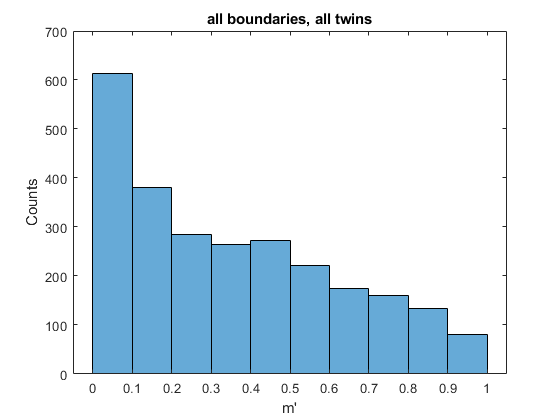

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('all boundaries, all twins');

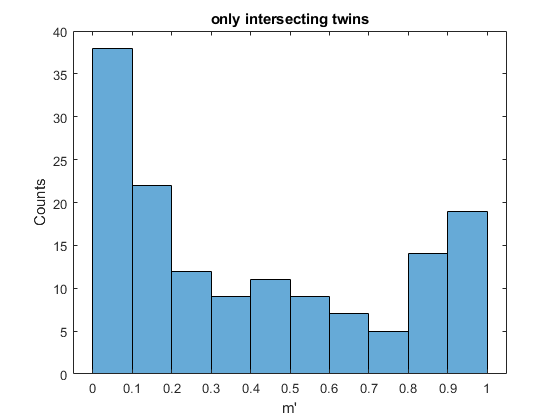


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('only intersecting twins');

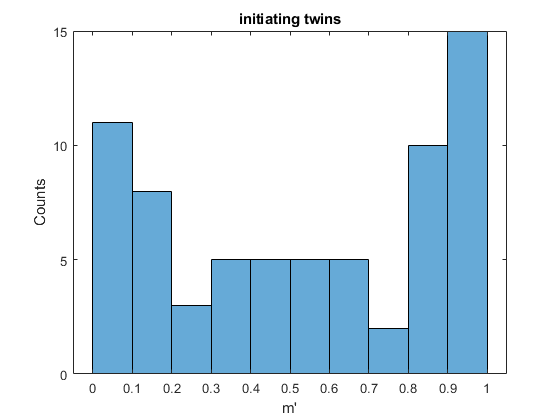


% (3) boundaries with initiating twins (triple points, grain size considered)  
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('initiating twins');

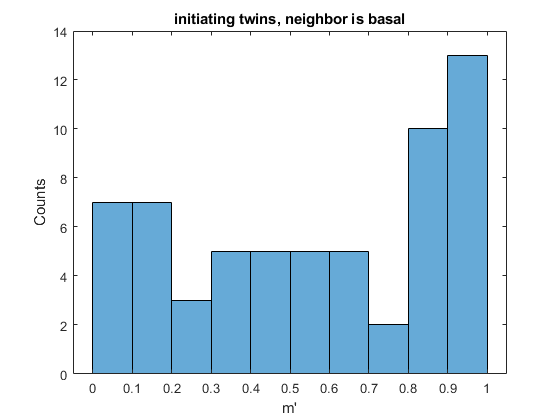


% (4) If only look at those paired with basal slip
ind = (T.incoming==1)&(T.initiating==1)&(ismember(T.ssn_neighbor,[1,2,3]));
t = T(ind,:);
figure;
histogram(t.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('initiating twins, neighbor is basal');

## (2) m' rank

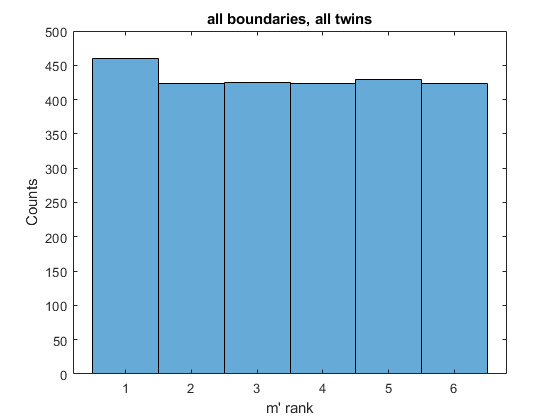

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('all boundaries, all twins');

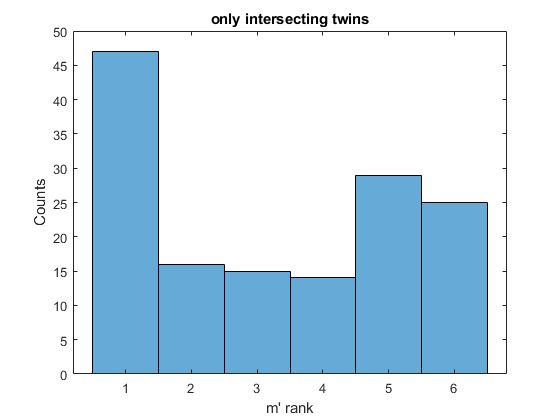


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('only intersecting twins');

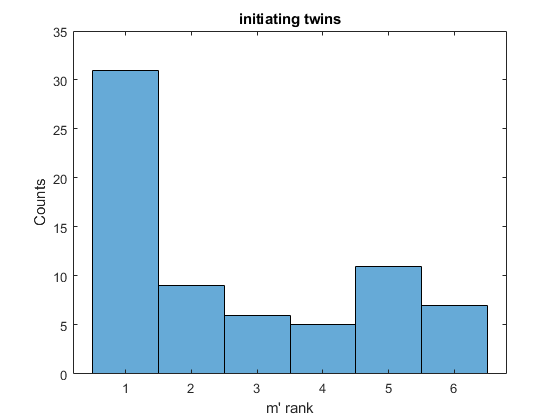


% (3) boundaries with initiating twins
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins');

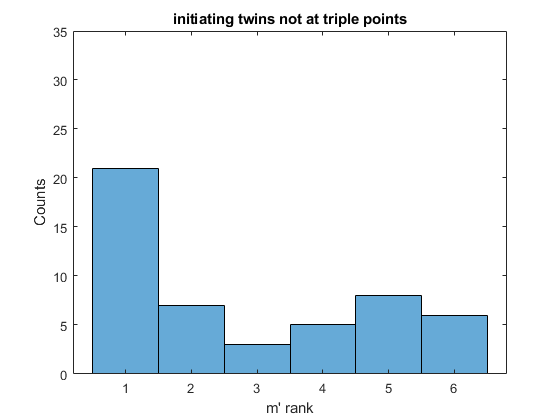

ylim = get(gca,'ylim');

% (4) divide by grain size
ind = (T.incoming==1)&(T.initiating==1)&(T.gDia>100)&(T.gDia_neighbor>100);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins not at triple points');
set(gca,'ylim',ylim);

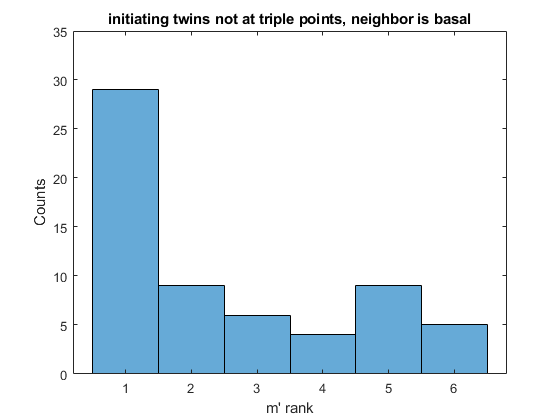


% (5) If only look at those paired with basal slip
ind = (T.incoming==1)&(T.initiating==1)&(ismember(T.ssn_neighbor,[1,2,3]));
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins not at triple points, neighbor is basal');
set(gca,'ylim',ylim);

## (3) resB

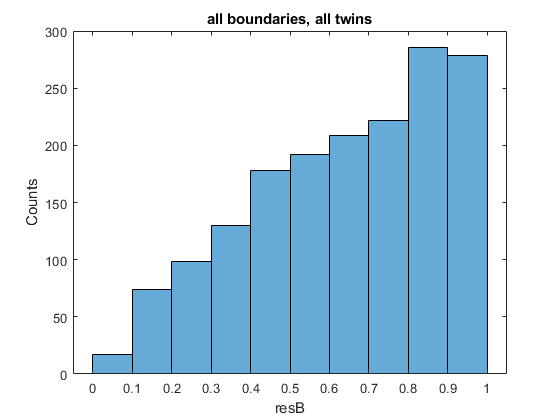

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.resB, 0:0.1:1);
xlabel('resB');
ylabel('Counts');
title('all boundaries, all twins');

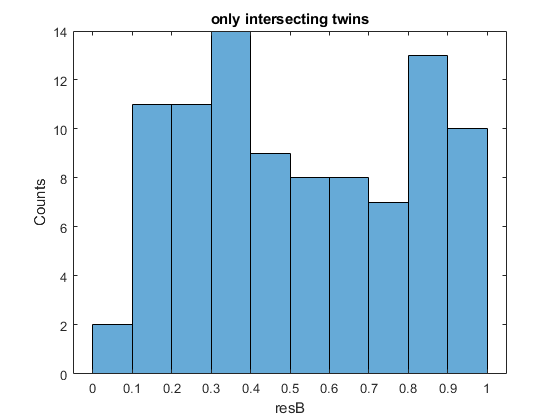


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.resB, 0:0.1:1);
xlabel('resB');
ylabel('Counts');
title('only intersecting twins');

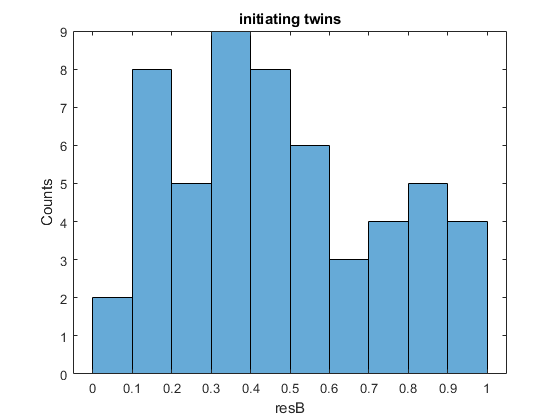


% (3) boundaries with initiating twins
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.resB, 0:0.1:1);
xlabel('resB');
ylabel('Counts');
title('initiating twins');

ylim = get(gca,'ylim');

## (4) resB_rank

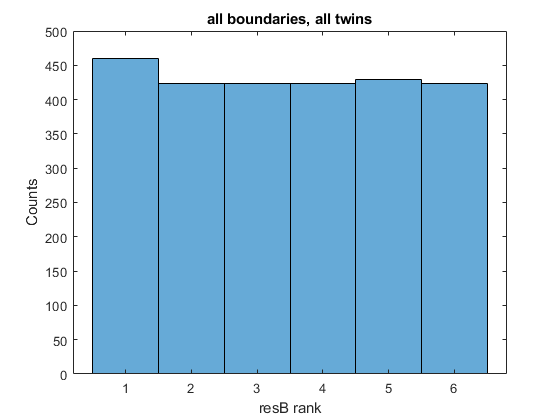

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.rank_resB, 0.5:6.5);
xlabel('resB rank');
ylabel('Counts');
title('all boundaries, all twins');

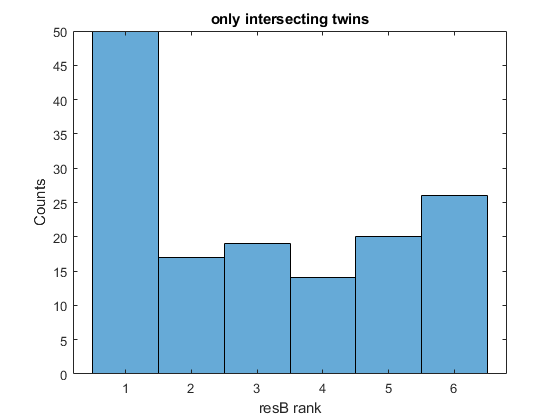


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.rank_resB, 0.5:6.5);
xlabel('resB rank');
ylabel('Counts');
title('only intersecting twins');

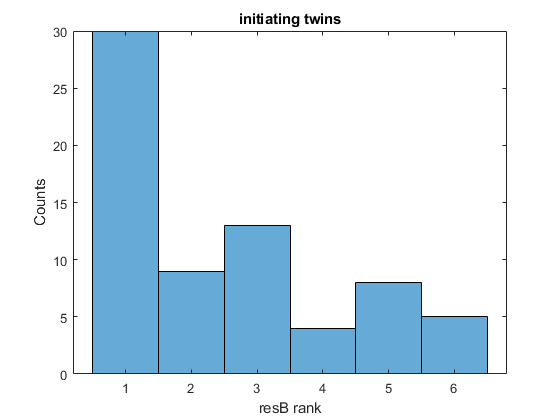


% (3) boundaries with initiating twins
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.rank_resB, 0.5:6.5);
xlabel('resB rank');
ylabel('Counts');
title('initiating twins');

ylim = get(gca,'ylim');

## This shows the relationship between m' rank and resB rank.

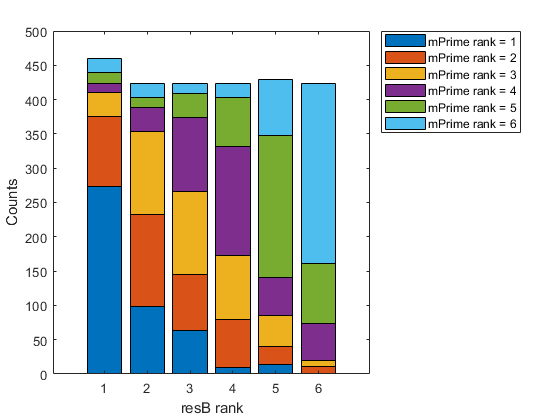

close all; 
colormap parula
edges = 0.5:6.5;
N = zeros(6,6);
for ii = 1:6
    ind = (T.rank_mPrime == ii);
    [N(:,ii),~] = histcounts(T.rank_resB(ind), edges);
end
figure;
bar(1:6, N, 'stacked');
xlabel('resB rank');
ylabel('Counts');
legend({'mPrime rank = 1','mPrime rank = 2','mPrime rank = 3','mPrime rank = 4','mPrime rank = 5','mPrime rank = 6'},'location','bestoutside');

## (5) m' vs neighbor_SF